# **Question 1(c)**

#### **plot of sigma P**

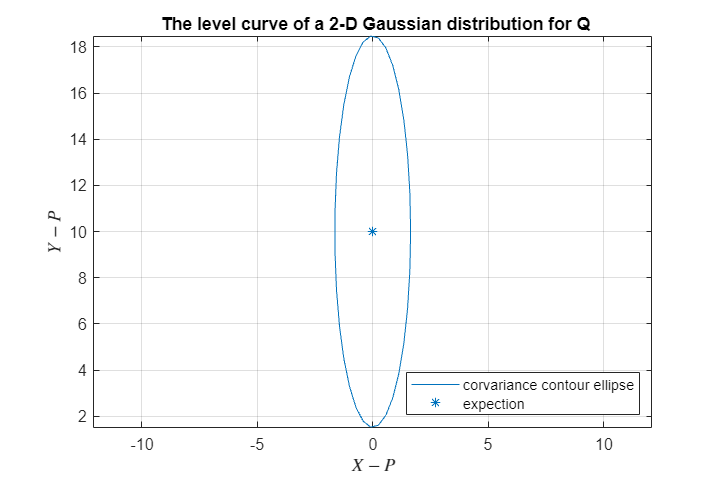

clear all
clc
mu_p=[0;10];sigma_p=[0.3 0;0 8];A=[1 0.5;0 1];b=zeros(2,1);

%Call your function.
xy_p = sigmaEllipse2D(mu_p, sigma_p);

%Now plot the generated points. You should see an elongated ellipse stretching from the top left corner to the bottom right. 
figure('Position',[300 300 600 400]);

h1 = plot(xy_p(1,:), xy_p(2,:));
%Set the scale of x and y axis to be the same. This should be done if the two variables are in the same domain, e.g. both are measured in meters.
axis equal
hold on
%Also plot a star where the mean is, and make it have the same color as the ellipse.
xlabel('$X-{P}$', 'Interpreter','latex') % Set x-axis label
ylabel('$Y-{P}$', 'Interpreter','latex') % Set y-axis label
title(' The level curve of a 2-D Gaussian distribution for Q')
grid on ;
plot(mu_p(1), mu_p(2), '*', 'color', h1.Color);
legend('corvariance contour ellipse','expection','location','southeast')
hold off

#### plot of sigma P

[mu_z, sigma_z] = affineGaussianTransform(mu_p, sigma_p, A, b)

mu_z =      5
    10


sigma_z =     2.3000    4.0000
    4.0000    8.0000


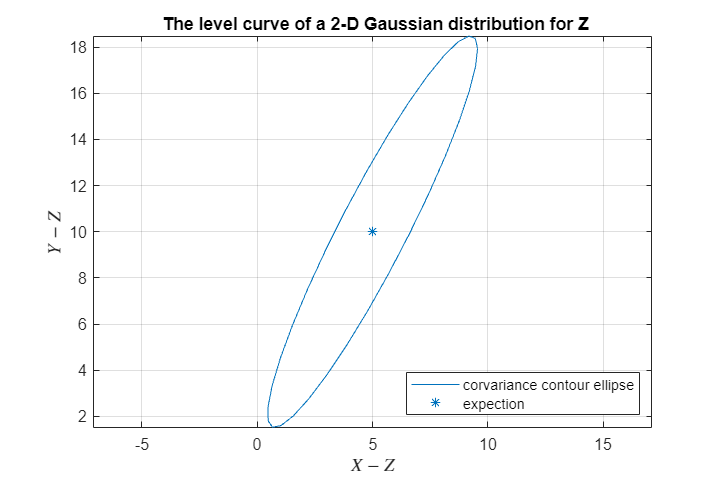

xy_z = sigmaEllipse2D(mu_z, sigma_z);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Now plot the generated points. You should see an elongated ellipse stretching from the top left corner to the bottom right. 
figure('Position',[300 300 600 400]);

h1 = plot(xy_z(1,:), xy_z(2,:));
%Set the scale of x and y axis to be the same. This should be done if the two variables are in the same domain, e.g. both are measured in meters.
axis equal
hold on
%Also plot a star where the mean is, and make it have the same color as the ellipse.
xlabel('$X-{Z}$', 'Interpreter','latex') % Set x-axis label
ylabel('$Y-{Z}$', 'Interpreter','latex') % Set y-axis label
title(' The level curve of a 2-D Gaussian distribution for Z')
grid on ;
plot(mu_z(1), mu_z(2), '*', 'color', h1.Color);
legend('corvariance contour ellipse','expection','location','southeast')
hold off

# Question2(a)


mu_x2=0;sigma_x2=2;
A2=3;b2=0;f=@(x)(3*x);N=10000;
[mu_z2, sigma_z2] = affineGaussianTransform(mu_x2, sigma_x2, A2, b2)

mu_z2 = 0

sigma_z2 = 18



[mu_z3, sigma_z3, y_z3] = approxGaussianTransform(mu_x2, sigma_x2, f, N)

mu_z3 = 0.0545

sigma_z3 = 18.4212

y_z3 =     2.3007    3.6017    1.3968    2.1331    1.2578    3.0233   -2.7857   -0.4556   -0.5773    5.2230    7.2577   -2.4382   -2.8912    1.4568    0.0391    7.9721   -0.0365    3.6141   -1.8090   -0.3743   -3.8428   -3.9121    1.5387   -1.8307   -5.6657   -1.4295   -1.9759   -3.6257   -0.7474    0.3574   -1.1254    3.7351    1.9175    6.4091   -2.5783    4.1736    0.0795    4.6758   -2.8406    3.3996   -6.2615   -4.4525   -0.8983    4.7043    2.5161   -7.7502    0.7862    3.7497   -0.9947    3.2908


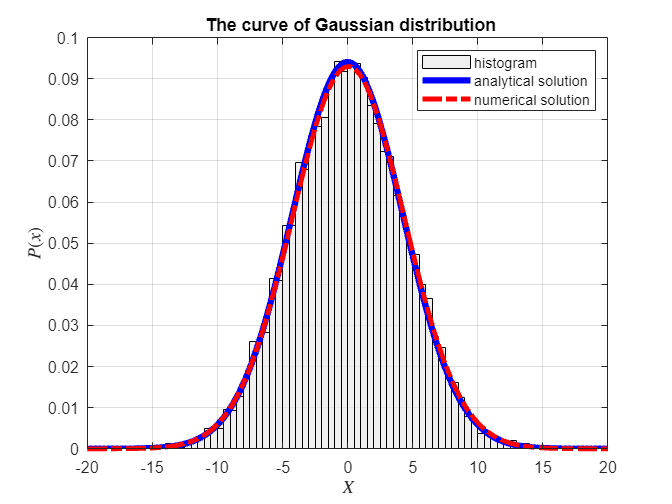

figure('Position',[300 300 600 400]);
histogram(y_z3,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x=[-20:0.1:20];
y=normpdf(x,mu_z2,sqrt(sigma_z2));
plot(x,y,'LineWidth',4,'color','blue')
hold on
y=normpdf(x,mu_z3,sqrt(sigma_z3));
plot(x,y,'LineStyle','-.','color','red','LineWidth',3)
legend('histogram','analytical solution','numerical solution')
xlabel('$X$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(x)$', 'Interpreter','latex') % Set y-axis label
grid on
title(' The curve of Gaussian distribution')

# Question2(b)

f2=@(x)(x^3);N=100000;
[mu_z4, sigma_z4, y_z4] = approxGaussianTransform(mu_x2, sigma_x2, f2, N)

mu_z4 = -0.0140

sigma_z4 = 121.2083

y_z4 =    -6.9829   -0.0001   -0.0919   -0.2422   -2.4005   -0.9959   -3.5445   -1.7240    0.6104    7.0084   -0.0149    4.2905    2.7542   -0.0003    0.0002    0.8091    0.7761   -1.6280   -2.6169   -0.0039    3.8818    1.0821   -1.3953   -0.0772   -2.0040   -0.3453   -1.7845   -4.2404   26.5053    6.2401   -0.5001   -0.7442   -0.1420    1.2365   -0.1007    0.3481    0.9503   -0.0156    0.9488    1.0871   -1.3338    0.0466  -10.8197   -0.0367   -0.6434    5.3287    3.3500   -0.6216    1.3030    0.2783


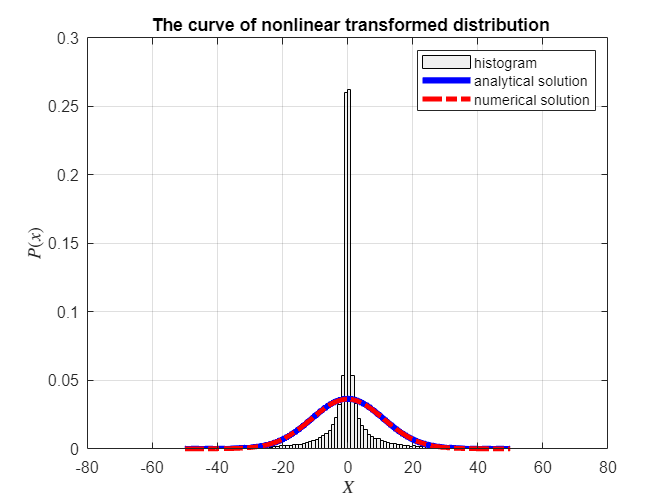

figure('Position',[300 300 600 400]);
histogram(y_z4,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x1=[-50:0.1:50];
xlim([-80,80])
y=normpdf(x1,0,sqrt(120));
plot(x1,y,'LineWidth',4,'color','blue')
hold on
y=normpdf(x1,mu_z4,sqrt(sigma_z4));
plot(x1,y,'LineStyle','-.','color','red','LineWidth',3)
legend('histogram','analytical solution','numerical solution')
xlabel('$X$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(x)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of nonlinear transformed distribution')
grid on
%nonlinear transform, not a Gaussian
hold off

# Question3

# P(y)

clear all
N=100000;
H21=@(x)(4*x);%linear function
a=10;b=20;
x31=[-200:1:200];
%assume sigma_r^2=25
X_uni=a+(b-a)*rand(1,N)%get samples using uniform distribution

X_uni =    14.7120   13.5472   18.3192   12.5067   11.4969   19.0106   17.2555   17.9209   17.8983   12.3685   10.8335   17.2895   17.9230   17.0991   16.4237   11.8366   15.2412   12.4727   18.4334   14.6667   18.9162   14.9520   16.1638   15.9059   14.4333   14.3934   12.1033   15.7833   12.5998   18.2315   17.9251   17.8531   13.4028   13.6104   18.4181   17.9241   14.3107   10.1317   12.7162   11.9341   13.3460   16.0628   11.4949   16.4193   12.8650   13.5121   19.6210   13.9945   18.3454   15.2452


r=mvnrnd(0, 25,N)'%get samples using normal distribution

r =    -1.4871    1.1758    4.2017    8.4614    0.7441    0.5567    1.7759    5.7772   -9.9509   -0.4451   -5.9754    7.2355   -4.6158   -1.4867    0.5072    2.1962    4.1114   -4.8437    0.0732   -6.5498    0.6372   -1.5573   -3.6641   -6.0316   -0.1695   -3.2305    6.1514    9.0604    0.0734    9.3048  -10.2622   -0.9363   -0.9450   -3.9427   -8.1558    2.5623   -0.9305   -3.0242   -2.6838    3.8447   -3.8760   -2.2699   -3.2870    2.5442   -4.5122    3.8532    1.5677  -10.7519   -2.8055    2.2010


% X_uni=unifpdf(x31,-20,20)
ys_3111=[];
for i=1:N
    ys_3111=[ys_3111,H21(X_uni(:,i))];%if it is uniform
end
ys31=[1 1]*[ys_3111;r];
figure('Position',[300 300 600 400]);
histogram(ys31,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
% figure()
% plot(normys31)
hold on
y=[0:0.1:100]

y =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


func=-(erf(8-y/5)+erf((y-80)/5))/(80)

func =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


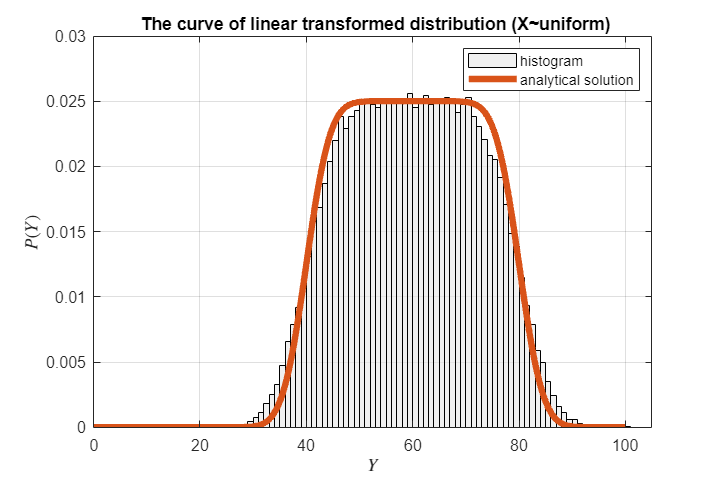

plot(y,func,'LineWidth',4)
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of linear transformed distribution (X~uniform)')
grid on
hold off

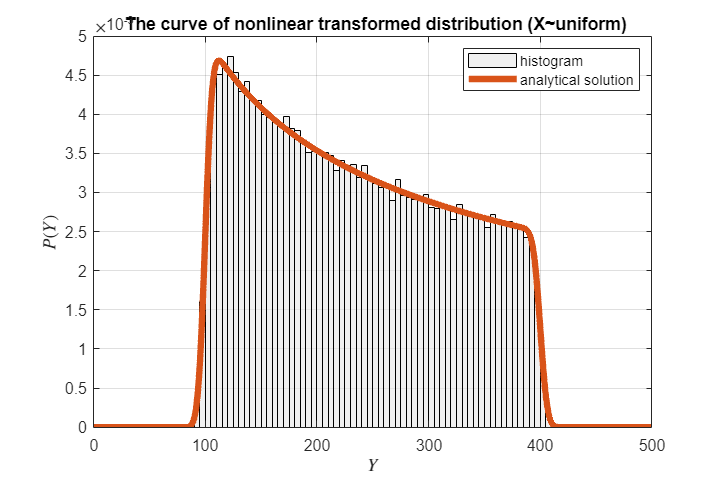

%Integrate[1/10*(1/(sqrt(2*pi*5^2)))*exp(-(y-x^2)^2/2*5^2),{x,10,20}]
H31=@(x)(x.^2);%nonlinear function
ys_3222=[];
for i=1:N
    ys_3222=[ys_3222,H31(X_uni(:,i))];%if it is uniform
end
ys32=[1 1]*[ys_3222;r];
figure('Position',[300 300 600 400]);
histogram(ys32,'Normalization','pdf','FaceColor',[.9 .9 .9]) 

Y=linspace(0,500,5000);
ys_analys=[];
for y=Y
    func=@(x) unifpdf(x,a,b).*normpdf(y,H31(x),5);
    ys_analys=[ys_analys integral(func,a,b)];
end
hold on
plot(Y,ys_analys,'LineWidth',4)
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of nonlinear transformed distribution (X~uniform)')
grid on
hold off

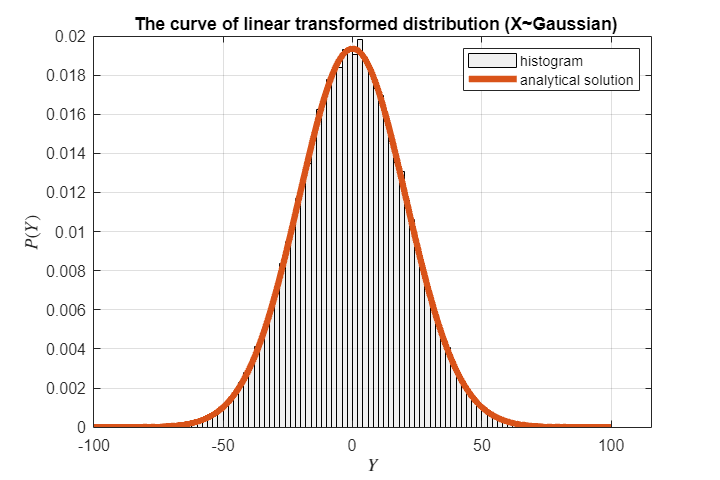

X_normal=mvnrnd(0, 25,N)';
ys_3333=[];
for i=1:N
    ys_3333=[ys_3333,H21(X_normal(:,i))];%if it is uniform
end
ys33=[1 1]*[ys_3333;r];
figure('Position',[300 300 600 400]);
histogram(ys33,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x_normal3=[-100:0.1:100];
y=normpdf(x_normal3,0,sqrt(425));
plot(x_normal3,y,'LineWidth',4)
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of linear transformed distribution (X~Gaussian)')
grid on
hold off

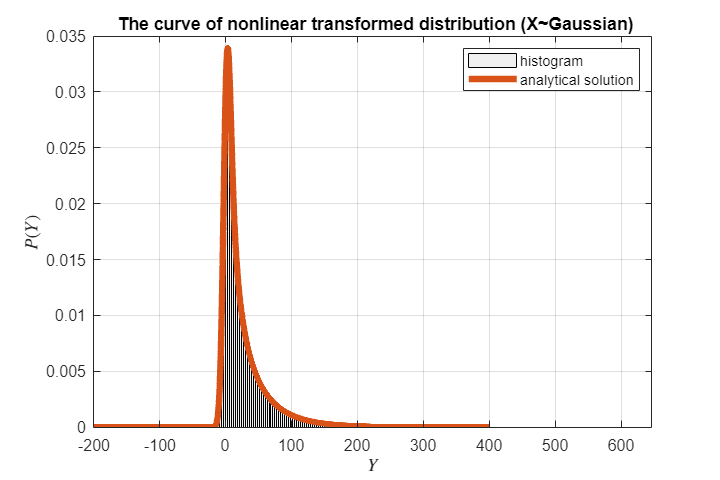

ys_3444=[];
for i=1:N
    ys_3444=[ys_3444,H31(X_normal(:,i))];%if it is uniform
end
ys34=[1 1]*[ys_3444;r];
figure('Position',[300 300 600 400]);
histogram(ys34,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on

Y=linspace(-200,400,5000);
ys_analys=[];
for y=Y
    func=@(x) normpdf(x,0,5).*normpdf(y,H31(x),5);
    ys_analys=[ys_analys integral(func,-15,15)];
end
hold on
plot(Y,ys_analys,'LineWidth',4)
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of nonlinear transformed distribution (X~Gaussian)')
grid on
hold off

# P(y|x)

%%%%%%uniform linear
X_rand=a+(b-a)*rand;
y_31pyx=r+H21(X_rand);
figure('Position',[300 300 600 400]);
histogram(y_31pyx,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x_normalyx1=[0:0.1:95];
y=normpdf(x_normalyx1,H21(X_rand),sqrt(25))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


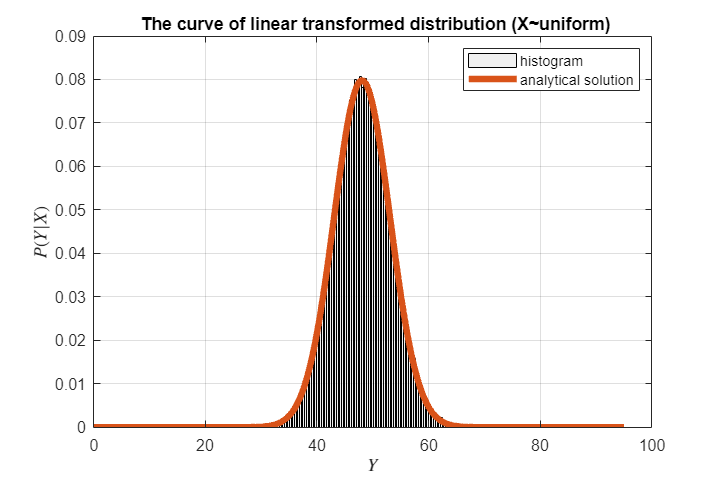

plot(x_normalyx1,y,'LineWidth',4)
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y|X)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of linear transformed distribution (X~uniform)')
grid on
hold off

%%%%%%uniform nonlinear
y_32pyx=r+H31(X_rand);
figure('Position',[300 300 600 400]);
histogram(y_32pyx,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
x_normalyx2=[0:0.1:250];
y=normpdf(x_normalyx2,H31(X_rand),sqrt(25))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


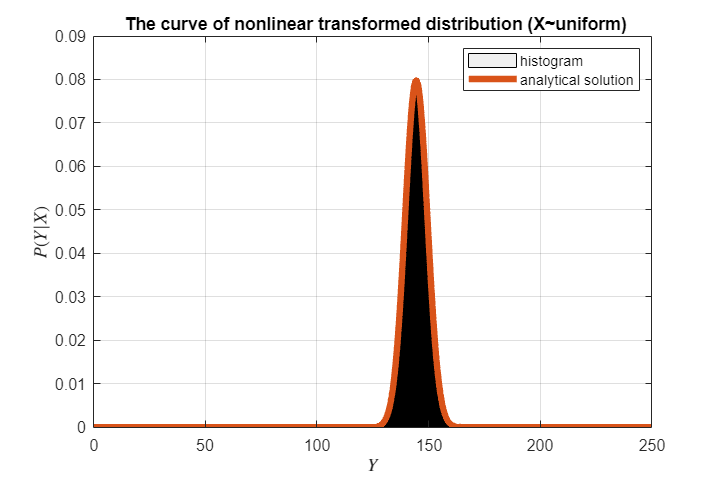

hold on
plot(x_normalyx2,y,'LineWidth',4)
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y|X)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of nonlinear transformed distribution (X~uniform)')
grid on
hold off

X_randn=mvnrnd(0, 25,1);

%%%%%%guassian linear
y_33pyx=r+H21(X_randn);
figure('Position',[300 300 600 400]);
histogram(y_33pyx,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
x_normalyx3=[-100:0.1:50];
hold on
y=normpdf(x_normalyx3,H21(X_randn),sqrt(25))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


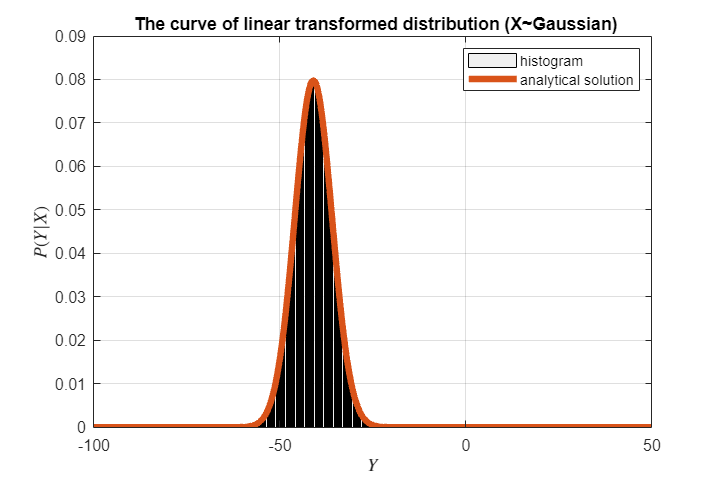

plot(x_normalyx3,y,'LineWidth',4)
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y|X)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of linear transformed distribution (X~Gaussian)')
grid on
hold off

%%%%%%guassian nonlinear
y_33pyx=r+H31(X_randn);
figure('Position',[300 300 600 400]);
histogram(y_33pyx,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
x_normalyx4=[-50:0.1:150];

hold on
y=normpdf(x_normalyx4,H31(X_randn),sqrt(25))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


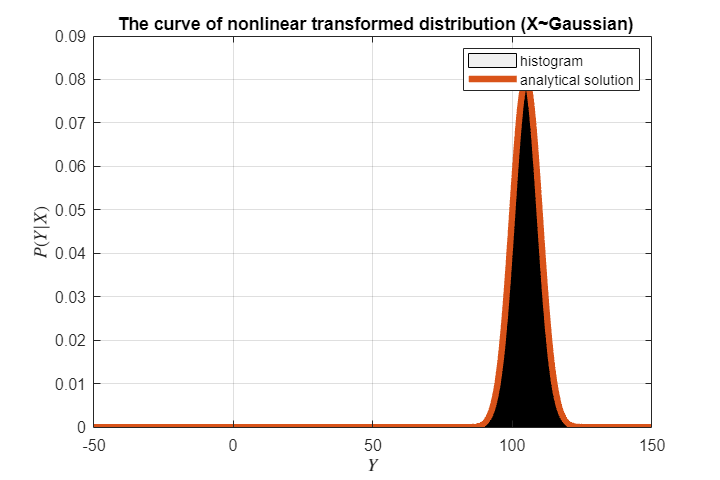

plot(x_normalyx4,y,'LineWidth',4)
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y|X)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of nonlinear transformed distribution (X~Gaussian)')
grid on
hold off

# Question4

sigma41=0.5^2;
N=100000;
x41=[-4:0.1:4];
y41=0.5*normpdf(x41,-1,sqrt(sigma41))+0.5*normpdf(x41,1,sqrt(sigma41));
figure('Position',[300 300 600 400]);
plot(x41,y41,'LineWidth',4);
hold on
w=(mvnrnd(0,sigma41,N))'

w =    -0.7237   -0.4346   -0.4557    0.4868   -0.3107    0.0904    0.3712    0.2764   -0.1939    0.1432    0.4100   -0.0209   -0.0885   -0.2616    0.2240    0.1410   -0.5280    0.2661    0.6045    0.0689   -0.3296    0.2556   -0.3974   -0.2861    0.3106    0.2154    0.2344   -0.3905   -0.3458   -0.2266   -0.1259    0.7126   -0.2767    0.0073    0.0348    0.3121   -0.6399    0.0270    0.8662   -0.0447   -0.6147    0.6643   -1.0949   -0.5738   -0.6159   -0.2718    0.5588   -0.1558    0.1906   -0.2174


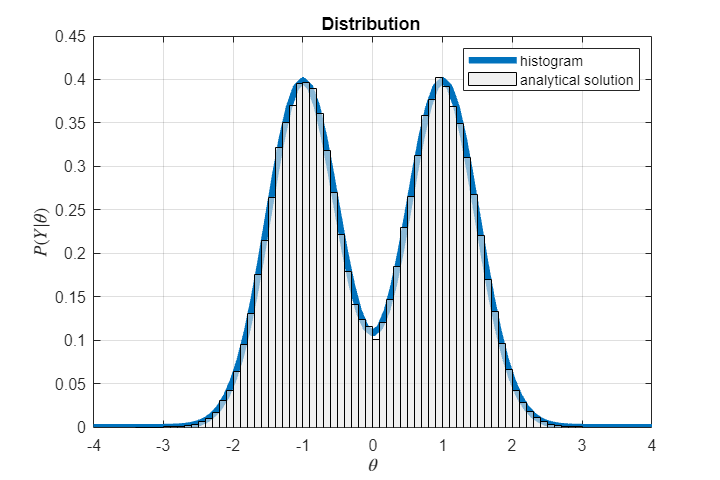

y42=[];
for i=1:N
    random_bit = randi([0, 1], 1, 1);
    if random_bit == 0
        theta = -1;
        y42=[y42 theta+w(i)];
    else
        theta = 1;
        y42=[y42 theta+w(i)];
    end
end
histogram(y42,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
legend('histogram','analytical solution')
xlabel('$\theta$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y|\theta)$', 'Interpreter','latex') % Set y-axis label
title('Distribution ')
grid on
hold off


y47=[-1.98:0.01:1.98];
theta_MMSE=[];
theta_MAP=[];

for i=1:size(y47,2)
    theta_MMSE=[theta_MMSE,(exp(-2*(y47(i)-1)^2)-exp(-2*(y47(i)+1)^2))/(exp(-2*(y47(i)-1)^2)+exp(-2*(y47(i)+1)^2))];
    if exp(4*y47(i))<1
        theta_MAP=[theta_MAP,-1];
    else
        theta_MAP=[theta_MAP,1];
    end
end
figure('Position',[300 300 600 400]);
plot(y47,theta_MMSE,'LineWidth',4)
hold on
plot(y47,theta_MAP,'LineWidth',4)
grid on
legend('\theta_{MMSE}','\theta_{MAP}','intepreter','latex')

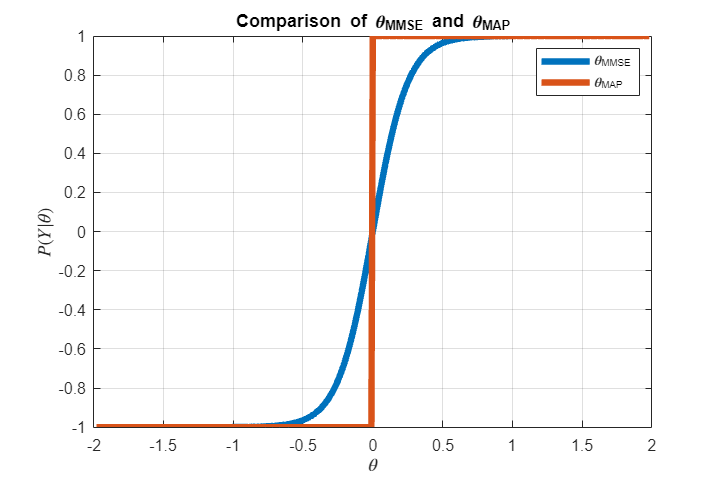

xlabel('$\theta$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y|\theta)$', 'Interpreter','latex') % Set y-axis label
title('Comparison of \theta_{MMSE} and \theta_{MAP}')
hold off

syms y sigma
S=simplify((exp(-(y-1)^2/(2*sigma^2))-exp(-(y+1)^2/(2*sigma^2)))/(exp(-(y-1)^2/(2*sigma^2))+exp(-(y+1)^2/(2*sigma^2))),'Steps',1000)

$$S = 1-\frac{2}{{\mathrm{e}}^{\frac{2\,y}{\sigma^{2}}}+1}$$

# function

function [ xy ] = sigmaEllipse2D( mu, Sigma, level, npoints )
%SIGMAELLIPSE2D generates x,y-points which lie on the ellipse describing
% a sigma level in the Gaussian density defined by mean and covariance.
%
%Input:
%   MU          [2 x 1] Mean of the Gaussian density
%   SIGMA       [2 x 2] Covariance matrix of the Gaussian density
%   LEVEL       Which sigma level curve to plot. Can take any positive value, 
%               but common choices are 1, 2 or 3. Default = 3.
%   NPOINTS     Number of points on the ellipse to generate. Default = 32.
%
%Output:
%   XY          [2 x npoints] matrix. First row holds x-coordinates, second
%               row holds the y-coordinates. First and last columns should 
%               be the same point, to create a closed curve.


%Setting default values, in case only mu and Sigma are specified.
if nargin < 3
    level = 3;
end
if nargin < 4
    npoints = 32;
end
phi=linspace(0,2*pi,npoints);
xy=zeros(2,npoints);
n=0;
for i=1:npoints
    xy(:,i)=mu+level*sqrtm(Sigma)*[cos(phi(:,i));sin(phi(:,i))];
end
%Your code here
%disp(size(xy,2))
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [mu_y, Sigma_y] = affineGaussianTransform(mu_x, Sigma_x, A, b)
%affineTransformGauss calculates the mean and covariance of y, the 
%transformed variable, exactly when the function, f, is defined as 
%y = f(x) = Ax + b, where A is a matrix, b is a vector of the same 
%dimensions as y, and x is a Gaussian random variable.
%
%Input
%   MU_X        [n x 1] Expected value of x.
%   SIGMA_X     [n x n] Covariance of x.
%   A           [m x n] Linear transform matrix.
%   B           [m x 1] Constant part of the affine transformation.
%
%Output
%   MU_Y        [m x 1] Expected value of y.
%   SIGMA_Y     [m x m] Covariance of y.

%Your code here
    mu_y=A*mu_x+b;%mu_z=E{AX+BY}=A*mu_x+B*mu_y
    Sigma_y=A*Sigma_x*A';%Sigma_z=Cov{AX+BY}=Cov{Ax}+Cov{By}
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [mu_y, Sigma_y, y_s] = approxGaussianTransform(mu_x, Sigma_x, f, N)
%approxGaussianTransform takes a Gaussian density and a transformation 
%function and calculates the mean and covariance of the transformed density.
%
%Inputs
%   MU_X        [m x 1] Expected value of x.
%   SIGMA_X     [m x m] Covariance of x.
%   F           [Function handle] Function which maps a [m x 1] dimensional
%               vector into another vector of size [n x 1].
%   N           Number of samples to draw. Default = 5000.
%
%Output
%   MU_Y        [n x 1] Approximated mean of y.
%   SIGMA_Y     [n x n] Approximated covariance of y.
%   ys          [n x N] Samples propagated through f


if nargin < 4
    N = 5000;
end

%Your code here
X = mvnrnd(mu_x, Sigma_x,N)';
% disp(size(X,1))
mu=zeros(size(mu_x,1),1);
y_s=[];
for i=1:N
    y_s=[y_s,f(X(:,i))];
end
mu_y=mean(y_s,2);
Sigma_y=(y_s-mu_y)*(y_s-mu_y)'/(N-1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [mu, Sigma] = jointGaussian(mu_x, sigma2_x, sigma2_r)
%jointGaussian calculates the joint Gaussian density as defined
%in problem 1.3a. 
%
%Input
%   MU_X        Expected value of x
%   SIGMA2_X    Covariance of x
%   SIGMA2_R    Covariance of the noise r
%
%Output
%   MU          Mean of joint density 
%   SIGMA       Covariance of joint density
A=[1 0;1 1];b=zeros(2,1);
mu_x=[mu_x,0]';
Sigma_x=[sigma2_x,0;0,sigma2_r];
[mu, Sigma] = affineGaussianTransform(mu_x, Sigma_x, A, b);
%Your code here
end